close all
clear

x = linspace(2,3,1e5);
xx = linspace(2,3,1e5);

f1 = @(z) sqrt(z.^2-1)-z;
f2 = @(z) -(1./sqrt(z.^2-1));
f3 = @(z) -(sqrt((z+1)./(z-1))-1);

funcs = {f1,f2,f3};
names = {"sqrt(z^2-1)-z","-1/sqrt(z^2-1)","-(sqrt((z+1)/(x-1))-1)"};
colors = {"b","r","m"};

f = @(z) -(1./sqrt(z.^2-1))

f = function_handle with value:
    @(z)-(1./sqrt(z.^2-1))


y = f(x);
[r, pol, res, zer, zj, fj, wj, errvec, wt, r_hist, p_hist, q_hist, pol_hist, res_hist, zer_hist, zj_hist, fj_hist, wj_hist] = aaa_history(y,x,"mmax",50,"tol",0,"t0",2);

as      

k = 10

k = 10

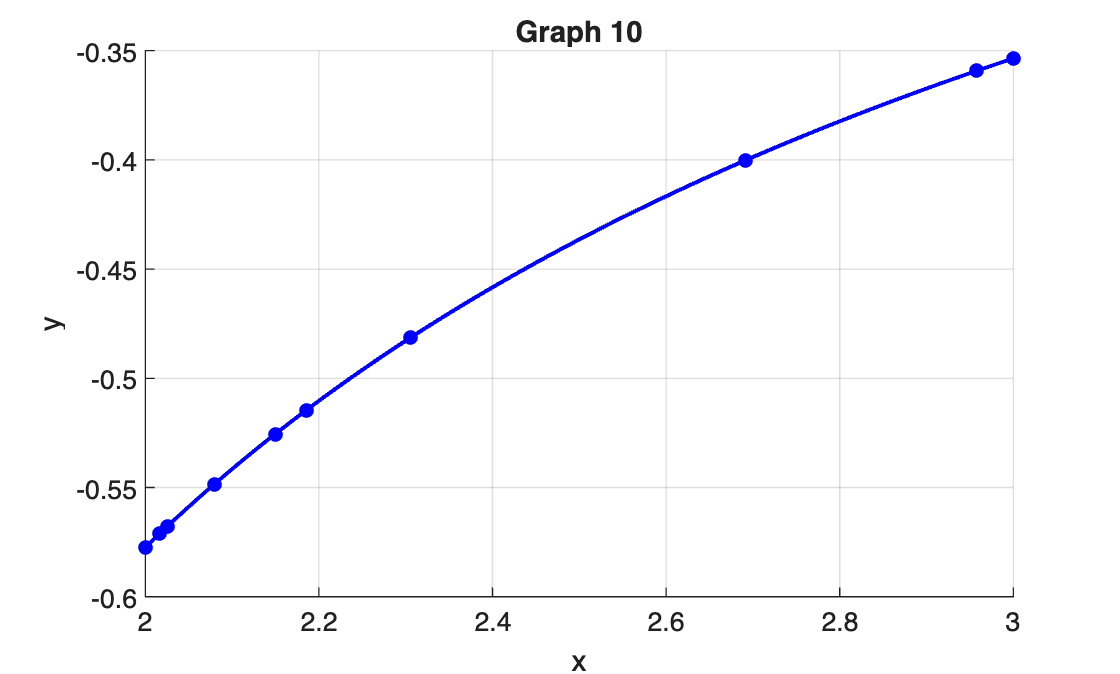

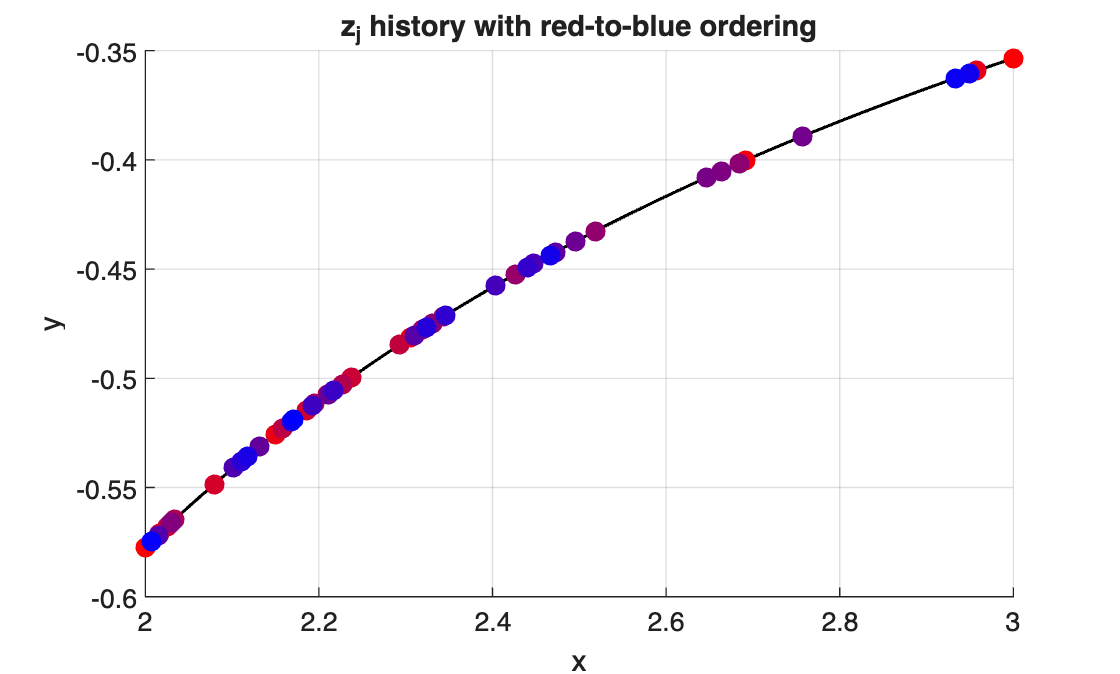

    figure
    hold on

    plot(xx, f(xx), "k", "LineWidth", 1.2)
    plot(xx, r_hist{k}(xx), "b", "LineWidth", 1.5)
    plot(zj_hist{k}, f(zj_hist{k}), "o", ...
        "Color", "b", ...
        "MarkerFaceColor", "b", ...
        "MarkerSize", 5)

    grid on
    xlabel("x")
    ylabel("y")
    title(sprintf("Graph %d", k))